# **Fun2Optimize**

Marek Wadinger

#### **Initialize Workspace**

clc; clear all; close all
addpath(genpath('functions'))

## **1. Formulate the optimization problem**

#### **Example Problem #1**

A rectangle is to be inscribed in the ellipse $\frac{x^2}{4}+y^2=1
$. What should be the dimensions of the rectangle to maximize its area? What is the maximum area?


$${min}\limits_{x,y}~ - 2x*2y \\
s.t. ~~\frac{x^2}{4}+y^2 = 1

$$


Where $x$ is half the width and $y$ is half the height of the rectangle.

**Use elimination method to remove make problem unconstrained**

Derive $y$ from constraint:


$$y = \sqrt{1 - \frac{x^2}{4} \\}
$$


Insert into cost function $J$:


$$J = -4x*\sqrt{1-\frac{x^2}{4}$$


f = @(x) -4*x*sqrt(1-x^2/4)

f = function_handle with value:
    @(x)-4*x*sqrt(1-x^2/4)


x0 = 0;
bounds = [0 2];

Following condition must be fulfilled $\surd \neq 0$:


$$1-\frac{x^2}{4} \neq 0 \longrightarrow
x \neq\pm 2
$$


**Example Problem #2**

#### Himmelblau’s function

The performance of numeric optimization algorithms is widely tested using finding local optima of the Himmelblau’s function. The function has four local minima and is given as follows


$$f(x,y) = (x^2+y-11)^2 +(x+y^2-7)^2$$


f = @(x,y) (x.^2 + y - 11).^2 + (x + y.^2 - 7).^2 ;
x0 = [2 2];         % initial point
bounds = [-6 6; -6 6]; % boundaries as whole domain of the function

## **2. Find the solution of the optimization problem**

Set 'Plot' option to True in any function to see convergence over iterations.

### Set initial parameters

t = 0.2;        % step size
alpha = 0.2;    % how much do we trust the linear extrapolation
beta = 0.5;     % coresponds to crudeness of the search
kmax = 500;     % max number of iterations 

### **Solve optimization problem**

#### **Gradient Method**

[x, fval] = gdm(f, x0, kmax, 't', t, 'Plot', false)

Optimum reached in:500 iterations... Time:0.031399s


x =    NaN   NaN


fval = NaN

#### **Gradient Method Backtracking**

[xb, fvalb] = gdmb(f, x0, kmax, 't', t, 'alpha', alpha, 'beta', beta, ...
                   'Plot', false)

Optimum reached in:500 iterations... Time:0.026384s


xb =     2.9305    2.1282


fvalb = 0.2918

#### **Newton Method**

[xn, fvaln] = newton(f, x0, kmax, 't', t, 'alpha', alpha, 'beta', beta, ...
                     'Plot', false)

Optimum reached in:59 iterations... Time:0.04636s


xn =     3.0000    2.0000


fvaln = 1.2063e-11

#### Luus Jaakola

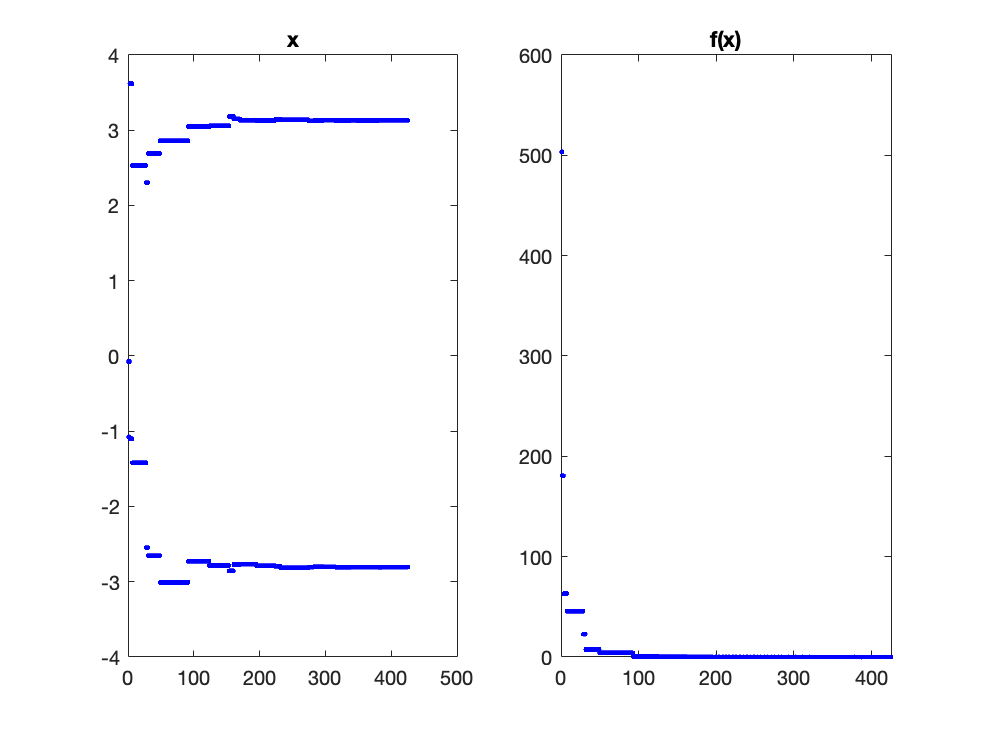

Optimum reached in:426 iterations... Time:4.6063s


xlj =    -2.8054    3.1316


fvallj = 6.5931e-06

[xlj, fvallj] = luusjaakola(f, '', kmax, bounds, 'ShrinkRate', 0.98, ...
                            'Plot', true)

#### Simulated annealing

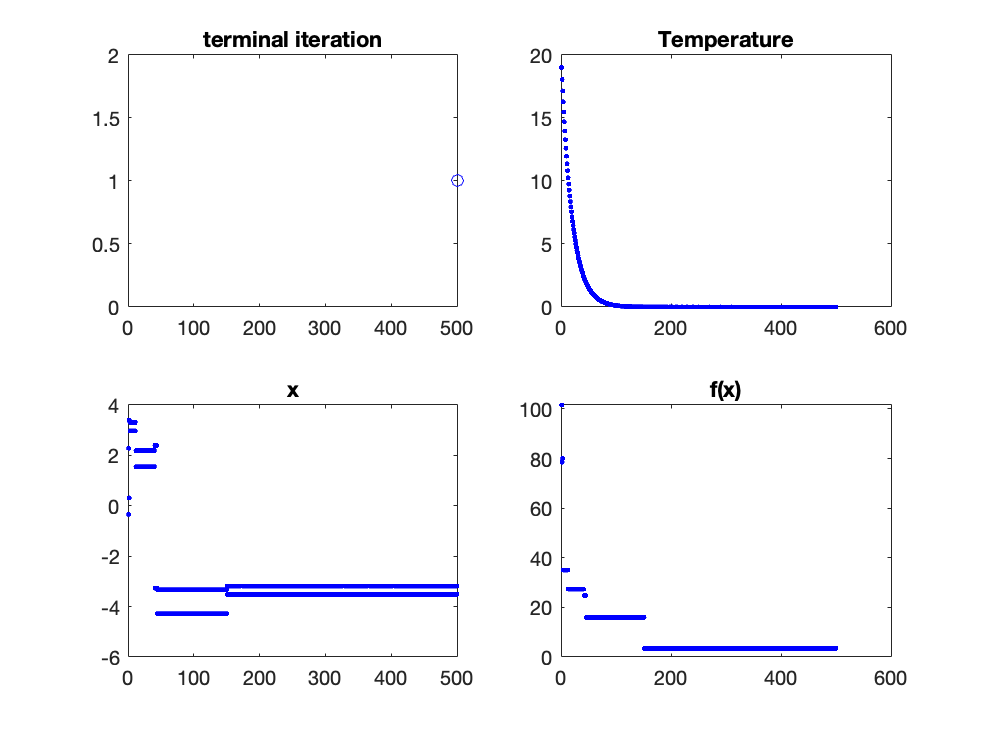

Optimum reached in:500 iterations... Time:22.4704s


xsa =    -3.5155   -3.1834


fvalsa = 3.4761

[xsa, fvalsa] = simulatedannealing(f, '' , kmax, bounds, ...
                                   'Temp', 20, 'T_reduction', 0.95, ...
                                   'Plot', true)

### Plot solutions for Example Problem #1

if nargin(f) ==1

Ellipse

clf(figure(1)); figure(1)
x_center = 0; y_center = 0;
fimplicit(@(x,y) (x-x_center).^2/4 ...
               + (y-y_center).^2 - 1, [-2,2]); hold on

Rectangle

cmp = colororder;
l_x_opts = [x, xb, xn, xlj, xsa];
for i = 1:length(l_x_opts)
    left = l_x_opts(i);
    bottom = sqrt(1-l_x_opts(i)^2/4);

    rectangle('Position',[x_center - left, ...
                      y_center - bottom, ...
                      left*2, ...
                      bottom*2], ...
                      'EdgeColor',cmp(i+1,:)', ...
                      'LineStyle',':', ...
                      'LineWidth',length(l_x_opts)-0.8*i);
    line(nan,nan,'Color',cmp(i+1,:))
end
hold off
legend('ellipse', ...
       'gradient', ...
       'gradient boost', ...
       'newton', ...
       'luus-jaakola', ...
       'simulated annealing')
end

## **3. Play with tunning parameters**

Choose optimization method and parameter from dropdown. Define range of values for which you would like to explore metrics (value of argument in optimum, value of cost function, time of optimization and number of iterations).	

opt_method_fcn = function_handle with value:
    @newton


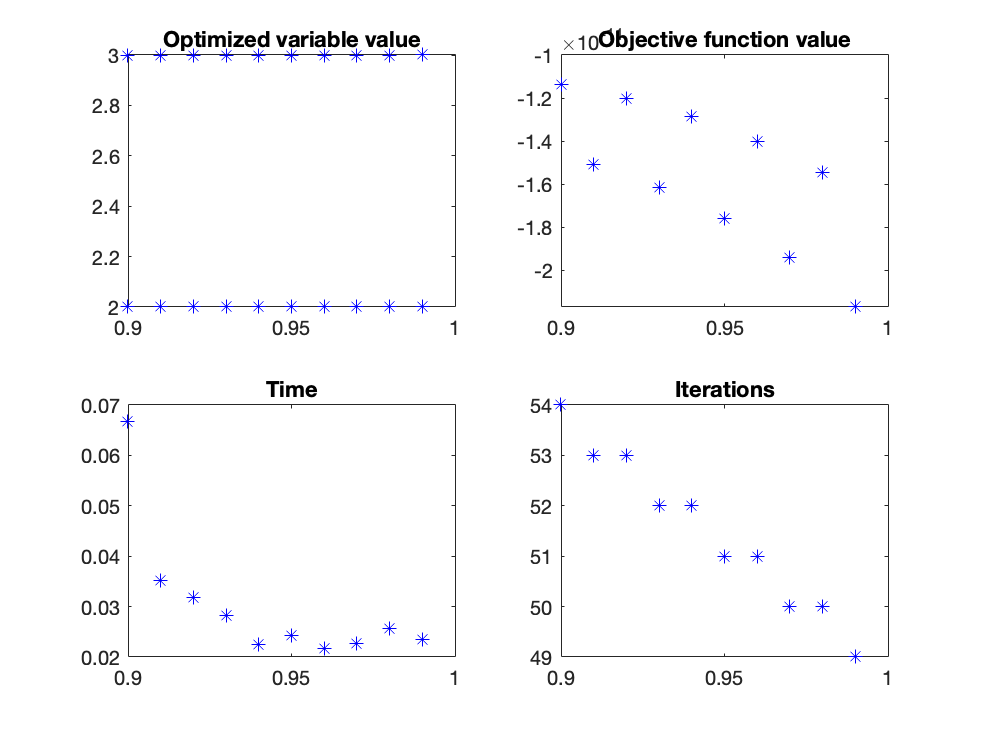

Step size t is inversely proportional to the number of iterations in backtracking. Small step size t results in slow convergence. The absolute value of a good step size is dependent on the optimization problem itself.


opt_method = "newton";
opt_param  = "t";
opt_values = 0.9:0.01:0.99;
 
optMethodDemo(f, x0, 500, bounds, opt_method, opt_param, opt_values);